
syms ang1 ang2 ang3 L1 L2 L3

xFormula = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
yFormula = (L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3));
x_dotFormula = diff(xFormula);
y_dotFormula = diff(yFormula);

x_ddotFormula = diff(diff(xFormula));
y_ddotFormula = diff(diff(yFormula));

h = [xFormula; yFormula; 0];
J = jacobian(h, [ang1 ang2 ang3])

$$J = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}\right)-L_{1}\,\sin\left({\mathrm{ang}}_{1}\right)-\sigma_{1} & -L_{2}\,\sin\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}\right)-\sigma_{1} & -\sigma_{1}\\ L_{2}\,\cos\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}\right)+L_{1}\,\cos\left({\mathrm{ang}}_{1}\right)+\sigma_{2} & L_{2}\,\cos\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}\right)+\sigma_{2} & \sigma_{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}+{\mathrm{ang}}_{3}\right)\\ \sigma_{2}=L_{3}\,\cos\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}+{\mathrm{ang}}_{3}\right) \end{array}$$

J_T = transpose(J);

otherJT = [ - L2*sin(ang1 + ang2) - L1*sin(ang1) - L3*sin(ang1 + ang2 + ang3), L2*cos(ang1 + ang2) + L1*cos(ang1) + L3*cos(ang1 + ang2 + ang3), 0;
               - L2*sin(ang1 + ang2) - L3*sin(ang1 + ang2 + ang3),                L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3), 0;
                                      -L3*sin(ang1 + ang2 + ang3),                                      L3*cos(ang1 + ang2 + ang3), 0]

$$otherJT = \begin{array}{l} \left(\begin{array}{ccc} -L_{2}\,\sin\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}\right)-L_{1}\,\sin\left({\mathrm{ang}}_{1}\right)-\sigma_{1} & L_{2}\,\cos\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}\right)+L_{1}\,\cos\left({\mathrm{ang}}_{1}\right)+\sigma_{2} & 0\\ -L_{2}\,\sin\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}\right)-\sigma_{1} & L_{2}\,\cos\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}\right)+\sigma_{2} & 0\\ -\sigma_{1} & \sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\sin\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}+{\mathrm{ang}}_{3}\right)\\ \sigma_{2}=L_{3}\,\cos\left({\mathrm{ang}}_{1}+{\mathrm{ang}}_{2}+{\mathrm{ang}}_{3}\right) \end{array}$$

 

ang1 = 1;
ang2 = 2;
ang3 = 3;
L1 = 1;
L2 = 2;
L3 = 3;
matrix = subs(J);


Jinv = transpose(matrix)

$$Jinv = \left(\begin{array}{ccc} -\sin\left(1\right)-2\,\sin\left(3\right)-3\,\sin\left(6\right) & \cos\left(1\right)+2\,\cos\left(3\right)+3\,\cos\left(6\right) & 0\\ -2\,\sin\left(3\right)-3\,\sin\left(6\right) & 2\,\cos\left(3\right)+3\,\cos\left(6\right) & 0\\ -3\,\sin\left(6\right) & 3\,\cos\left(6\right) & 0 \end{array}\right)$$



syms ang1 ang2 ang3 L1 L2 L3

xFormula = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
yFormula = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);
x_dotFormula = diff(xFormula);
y_dotFormula = diff(yFormula);

h = [x_dotFormula; y_dotFormula; 0];
J = jacobian(h, [ang1 ang2 ang3]);
J_T = transpose(J);

Analysis of the relationship between 2 optimisation metrics and the robots joints range of motions:

max) det(JJ^T)

Algebra

syms ang1 ang2 ang3 L1 L2 L3 phi real 

L1 = 1;
L2 = 1;
L3 = 1;

phi = ang1 + ang2 + ang3;


Posx = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
Posy = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);

Pwx = L1*cos(ang1) + L2*cos(ang1 + ang2);
Pwy = L1*sin(ang1) + L2*sin(ang1 + ang2);

c2 = (Pwx^2 + Pwy^2 - L1^2 - L2^2)/(2*L1*L2);

s2 = sqrt(1-c2^2);

ang2 = atan2(s2,c2);

c1 = ((L1 + L2*c2)*Pwy - L2*s2*Pwx)/(Pwx^2 + Pwy^2);
s1 = ((L1 + L2*c2)*Pwx + L2*s2*Pwy)/(Pwx^2 + Pwy^2);

ang1 = atan2(s1,c1);


ang3 = phi - ang1 - ang2;


J = [-L1*sin(ang1)-L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L3*sin(ang1+ang2+ang3);
    L1*cos(ang1)+L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L3*cos(ang1+ang2+ang3)];
J_T = transpose(J);


detminJ = det(J *J_T);




Numerical


L1 = 0.2817;
L2 = 0.2689;
L3 = 0.0862;

px = 0;
py = 0;
phi = 0;



%phi = ang1 + ang2 + ang3;


%Posx = L1*cos(ang1) + L2*cos(ang1 + ang2) + L3*cos(ang1 + ang2 + ang3);
%Posy = L1*sin(ang1) + L2*sin(ang1 + ang2) + L3*sin(ang1 + ang2 + ang3);

%Pwx = L1*cos(ang1) + L2*cos(ang1 + ang2);
%Pwy = L1*sin(ang1) + L2*sin(ang1 + ang2);

Pwx = px - L3*cos(phi);
Pwy = py - L3*sin(phi);

c2 = (Pwx^2 + Pwy^2 - L1^2 - L2^2)/(2*L1*L2);
if c2 > 1
    
   s2 = NaN;
   %not a number
else
    
s2 = sqrt(1-c2^2);

ang2 = atan2(s2,c2);

c1 = ((L1 + L2*c2)*Pwy - L2*s2*Pwx)/(Pwx^2 + Pwy^2);
s1 = ((L1 + L2*c2)*Pwx + L2*s2*Pwy)/(Pwx^2 + Pwy^2);

ang1 = atan2(s1,c1);


ang3 = phi - ang1 - ang2;


J = [-L1*sin(ang1)-L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L2*sin(ang1+ang2)-L3*sin(ang1+ang2+ang3), -L3*sin(ang1+ang2+ang3);
    L1*cos(ang1)+L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L2*cos(ang1+ang2)+L3*cos(ang1+ang2+ang3), L3*cos(ang1+ang2+ang3)];
J_T = transpose(J);


detminJ = det(J *J_T);


    
end



Changed to be function


px = 0.62;
py = 0;

phi = linspace(1, 360, 360*100)*2*pi/360; 
detJJ = phi;

xTest = 1;
linspaceX = linspace(0, 0.62, xTest);
maxdetJJ = zeros(2, xTest);
for index = 1:length(linspaceX)
    px = linspaceX(index);
for angle = 1:length(phi)
    detJJ(angle) = calcDetJJ(phi(angle), px, py); 
end
[maxVal, indexMax] = max(detJJ);
maxdetJJ(:,index) = [phi(indexMax)*360/(2*pi), maxVal];
end
maxdetJJ

maxdetJJ =    25.8216
    0.0027


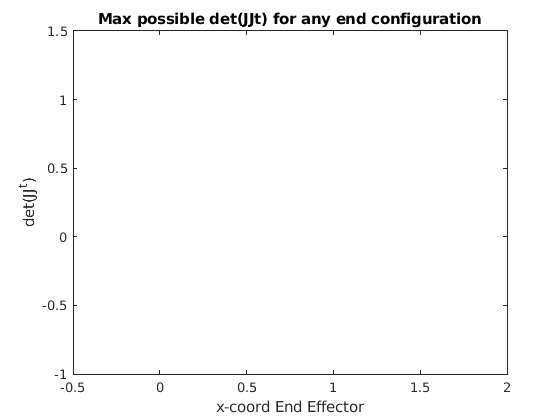

figure
plot(linspaceX, maxdetJJ(2,:))
xlabel('x-coord End Effector')
ylabel('det(JJ^t)')
title('Max possible det(JJt) for any end configuration')

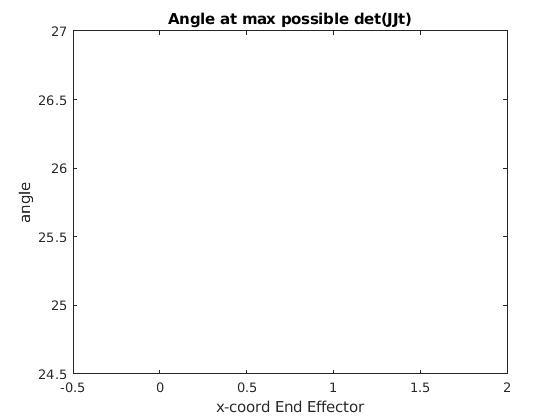


figure
plot(linspaceX, maxdetJJ(1,:))
xlabel('x-coord End Effector')
ylabel('angle')
title('Angle at max possible det(JJt)')